clear; close all; clc;

# BASIC OFDM PRINCIPLES, SIGNAL PROPERTIES,  CYCLIC PREFIX, DATA RATE

## 1. OFDM SIGNAL

### 1.1 OFDM BASICS AND SYMBOL GENERATION

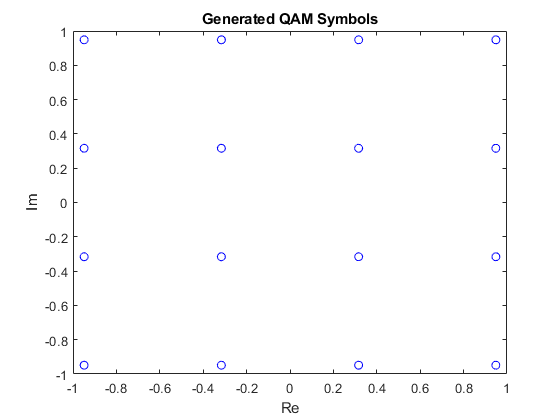

Nsym = 50; % Number of OFDM symbols (in time)
Nsubcarr = 1000; % 1000 subcarriers in band
Nactive = 600; % 600 active subcarriers (which contain data)
Modulation_order = 16; % 16-QAM modulation = 4 bits per symbol
bits = randi([0 Modulation_order-1],Nactive,Nsym); %Generate bits at random
QAMsymbols = qammod(bits,Modulation_order,'UnitAveragePower',true); 
%M-QAM modulation of the bits (see help qammod)

figure 
plot(QAMsymbols,'bo') 
xlabel('Re') 
ylabel('Im') 
title('Generated QAM Symbols')


% create 1 training symbol at the start of the sequence
training = ones(Nactive,1);
QAMsymbols(:,1) = training;

### 1.2 OFDM SYMBOL GENERATION, SPECTRUM

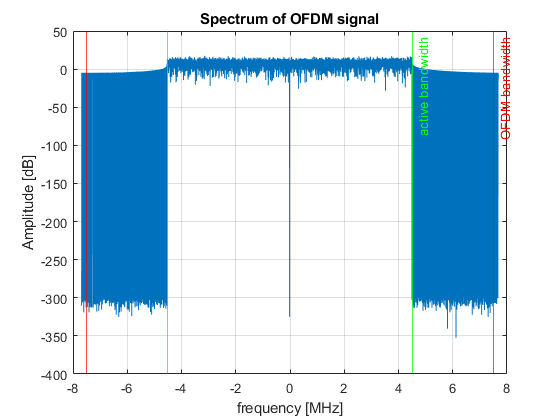

df = 15e3; % 15 kHz subcarrier spacing 
Tsym = 1/df; % symbol duration in seconds
FFT_size = 1024; % size of FFT
Fs = FFT_size*df; % sampling frequency
Ts = 1/Fs; % sampling interval
Fc = 800e6; % 800 MHz carrier frequency

subcarrier_mapping = [QAMsymbols(1:Nactive/2,:);...
zeros(FFT_size-(Nactive)-1,Nsym);...
QAMsymbols(end-Nactive/2:end-1,:);...
zeros(1,Nsym)];
%just fill the subcarieers of -30 to 30 

%modulating the data into freq. not time domain ---> into time domain
%(iffft)


ofdm_symbol = ifft(subcarrier_mapping, FFT_size);
test = ofdm_symbol(:);
figure;
OFDM_freq = fftshift(fft(ofdm_symbol(:),FFT_size*8));
freq_axis = -(Fs/2):Fs/length(OFDM_freq):Fs/2-Fs/length(OFDM_freq);
freq_axis = freq_axis/10^6;
bandwidth = Nsubcarr*df;
activebandwidth = Nactive*df;
plot(freq_axis, 10*log10(OFDM_freq.*conj(OFDM_freq)))
xline(-bandwidth/2e6,'- r')
xline(bandwidth/2e6,'- r',{'OFDM bandwidth'})
xline(-activebandwidth/2e6,'- g')
xline(activebandwidth/2e6,'- g',{'active bandwidth'})
grid on
hold on
xlabel('frequency [MHz]')
ylabel('Amplitude [dB]')
title('Spectrum of OFDM signal')

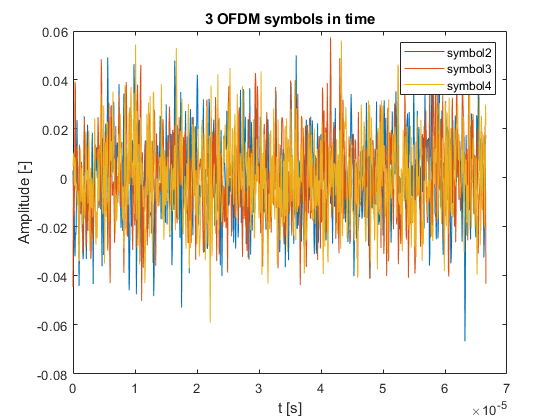


three_symbols = ofdm_symbol(:,[2:4]);
N=length(three_symbols);
T_three_symbol = 0:Ts:(N-1)*Ts; 
figure;
plot(0:Ts:Tsym-Ts, real(ofdm_symbol(:,2:4)))
%plot(T_three_symbol, imag(three_symbols))
xlabel('t [s]')
ylabel('Amplitude [-]')
title('3 OFDM symbols in time')
legend('symbol2','symbol3', 'symbol4')

## 2 CYCLIC PREFIX

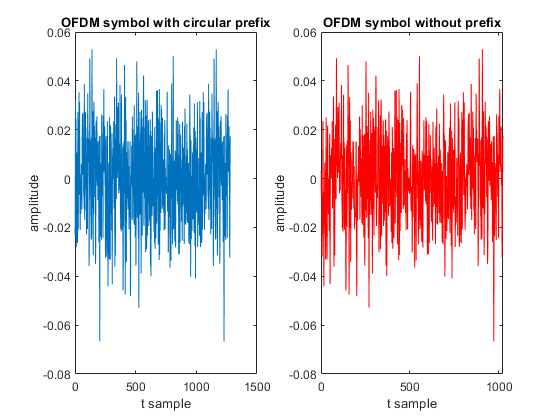

symbol = ofdm_symbol(:,2); % pick 1st ODFM symbol
cp_length = 1/4*length(symbol); 
% consider cp length of 1/4 of the symbol duration
cp = symbol(end-cp_length+1:end); % copy the end part of the symbol
cp_symbol = [cp;symbol]; 
% add the end part of the symbol to the beginning
Tsym_cp = Tsym+1/4*Tsym; 

% the duration of each symbol increases accordingly
%by adjusting time and frequency into small slots
%cyclic prefix to divide one symbol from another



figure
subplot(1,2,1)
plot(real(cp_symbol))
xlabel('t sample')
ylabel('amplitude')
title('OFDM symbol with circular prefix')
subplot(1,2,2)
plot(real(symbol),'r')
xlabel('t sample')
ylabel('amplitude')
title('OFDM symbol without prefix')


%N_symbol=length(cp_symbol);
% freq_cp_symbol = 0:Ts:(N_symbol-1)*Ts; 
% freq_symbol = 0:Ts:Ts*(length(symbol)-1);
% figure
% plot(freq_cp_symbol, 10*log10(cp_symbol.*conj(cp_symbol)))
% hold on
% plot(freq_symbol, 10*log10(symbol.*conj(symbol)))
% xlabel('t [s]')
% ylabel('Amplitude [-]')
% title('one OFDM symbols in time domain')
% legend('OFDM symbol with cyclic prefix', 'original OFDM symobl')
% legend('Position',[0.25124,0.15878,0.66879,0.13771])

cp_length = 2e-6; % cp length 2 microseconds % the lenght of cp should be equal to 
cp_length_samples = round(cp_length/Ts); % equal to 31 samples
cp = ofdm_symbol(end-cp_length_samples+1:end,:);
cp_ofdm_symbol = [cp;ofdm_symbol];
Tsym_cp = Tsym+Ts*cp_length_samples;
T_cp = [0:Ts:Tsym_cp-Ts]'; % Time vector for the symbols
T_nocp = [0:Ts:Tsym-Ts]';

##  3 DATA RATE

Rbit16 = Nactive * log2(Modulation_order) / Tsym

Rbit16 = 36000000

Rbit16max = Nsubcarr * log2(Modulation_order) / Tsym

Rbit16max = 60000000

Rbit16cp = Nactive * log2(Modulation_order) / Tsym_cp

Rbit16cp = 3.4942e+07

Rbit256 = Nactive * log2(256)/Tsym

Rbit256 = 72000000

##  4 CHANNEL MODEL WITH MULTIPATH PROPAGATION

delays = [0 1e-6 1.4e-6];
gains = [0 -1 -3];
Channel = comm.RayleighChannel('SampleRate',Fs,'PathDelays',delays,'AveragePathGains' ...
    ,gains,'MaximumDopplerShift',0);
release(Channel);
Channel.Visualization = 'Impulse and frequency responses';
Channel.SamplesToDisplay = '10%';
Rx_symbols_cp = zeros(size(cp_ofdm_symbol)); % prepare an empty matrix for received symbols

##  5 TRANSMISSION LOOP: TRANSMITTER – CHANNEL – RECEIVER

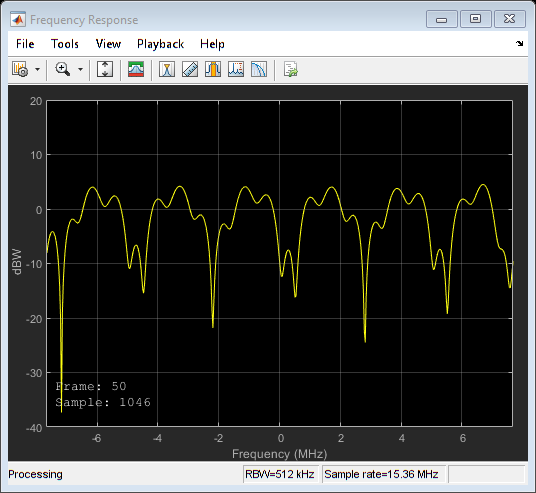

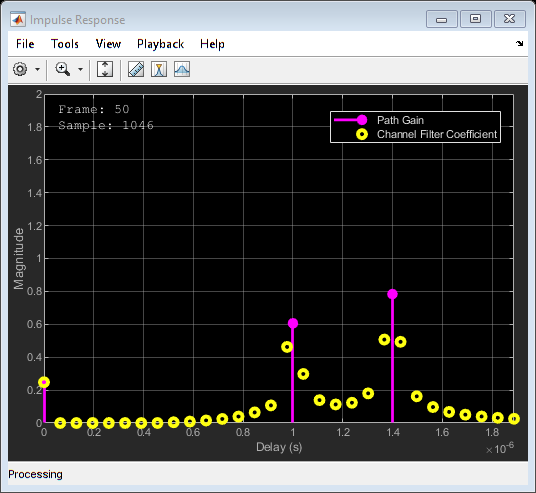

% instead of parallel to serial transformation, send symbols in a loop
for symb = 1:Nsym
    Tx_ofdm_cp = cp_ofdm_symbol(:,symb); % symbol by sybol transfer
    Tx_ofdm_cp = Tx_ofdm_cp.*exp(1j*2*pi*Fc*T_cp); % move signal to the 
    % carrier frequency band
    Rx_ofdm_cp = step(Channel,Tx_ofdm_cp);
    % Receiver design
    Rx_ofdm_cp = Rx_ofdm_cp.*exp(-1j*2*pi*Fc*T_cp); % Move bandpass 
    % signal back to >> lowapss frequencies
    Rx_symbols_cp(:,symb) = Rx_ofdm_cp; % Transform symbol-wise
end


%After receiving the symbols, execute the following operations:
Rx_symbols = Rx_symbols_cp(cp_length_samples+1:end,:); % Remove CP
Rx_fft = fft(Rx_symbols,FFT_size); % DFT
Rx_nopadding = [Rx_fft(1:Nactive/2,:); Rx_fft(end-Nactive/2:end-1,:)]; % select the active subcarriers
Channel_estimation = Rx_nopadding(:,1)./QAMsymbols(:,1); 
% apply Zero-Forcing channel equalizer
Equalizer = 1./Channel_estimation;
for k = 1:Nsym-1
    equalized_symbols(:,k) = Rx_nopadding(:,k+1).*Equalizer; % equalize symbols
end
Rxbits = qamdemod(equalized_symbols,Modulation_order,'UnitAveragePower',true); 
%M-QAM demodulation

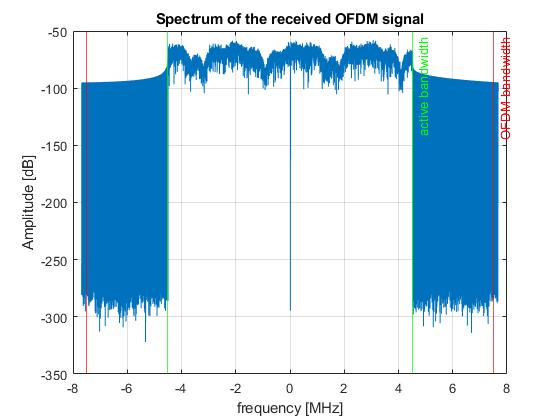



% plot the amplitude spectrum of the received OFDM signal
figure;
OFDM_freq = ifftshift(ifft(Rx_symbols(:),FFT_size*8));
freq_axis = -(Fs/2):Fs/length(OFDM_freq):Fs/2-Fs/length(OFDM_freq);
freq_axis = freq_axis/10^6;
bandwidth = Nsubcarr*df;
activebandwidth = Nactive*df;
plot(freq_axis, 10*log10(OFDM_freq.*conj(OFDM_freq)))
xline(-bandwidth/2e6,'- r')
xline(bandwidth/2e6,'- r',{'OFDM bandwidth'})
xline(-activebandwidth/2e6,'- g')
xline(activebandwidth/2e6,'- g',{'active bandwidth'})
grid on
hold on
xlabel('frequency [MHz]')
ylabel('Amplitude [dB]')
title('Spectrum of the received OFDM signal')

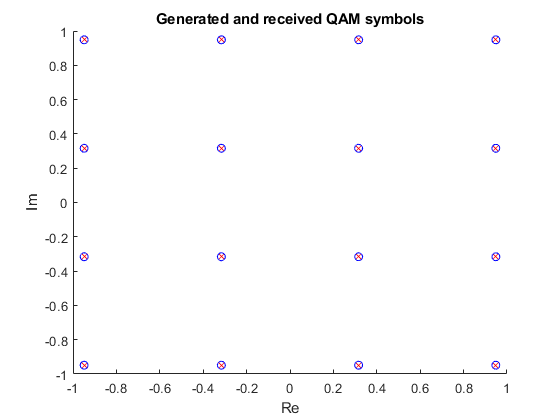


%To check whether the system works correctly, 
% plot the transmitted and received symbols in complex plane.
figure
hold on; 
plot(equalized_symbols(:,4),'rx');
plot(QAMsymbols(:,2:end),'bo');
xlabel('Re')
ylabel('Im')
title('Generated and received QAM symbols')

## 6 MODEL TESTING

Equalizer = 1

Equalizer = 1

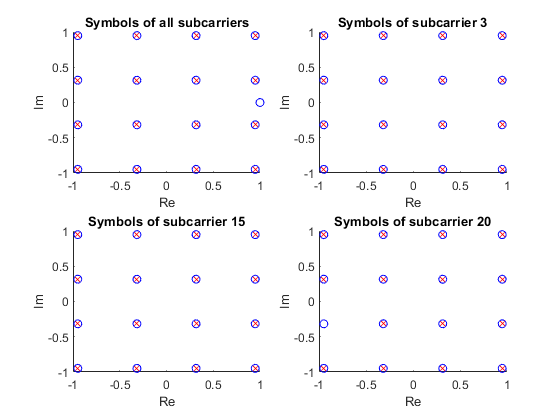

figure
subplot(2,2,1)
hold on;plot(equalized_symbols,'rx');plot(QAMsymbols,'bo');
xlabel('Re')
ylabel('Im')
title('Symbols of all subcarriers')
subplot(2,2,2)
hold on;
plot(equalized_symbols(3,:),'rx');plot(QAMsymbols(:,2:end),'bo');
xlabel('Re')
ylabel('Im')
title('Symbols of subcarrier 3')
subplot(2,2,3)
hold on;
plot(equalized_symbols(15,:),'rx');plot(QAMsymbols(:,2:end),'bo');xlabel('Re')
ylabel('Im')
title('Symbols of subcarrier 15')
subplot(2,2,4)
hold on;
plot(equalized_symbols(20,:),'rx');plot(QAMsymbols(:,2:end),'bo');xlabel('Re')
ylabel('Im')
title('Symbols of subcarrier 20')